## Example

Ldomain = 1

Ldomain = 1

x = linspace(-Ldomain, Ldomain, 1000)

x =    -1.0000   -0.9980   -0.9960   -0.9940   -0.9920   -0.9900   -0.9880   -0.9860   -0.9840   -0.9820   -0.9800   -0.9780   -0.9760   -0.9740   -0.9720   -0.9700   -0.9680   -0.9660   -0.9640   -0.9620   -0.9600   -0.9580   -0.9560   -0.9540   -0.9520   -0.9499   -0.9479   -0.9459   -0.9439   -0.9419   -0.9399   -0.9379   -0.9359   -0.9339   -0.9319   -0.9299   -0.9279   -0.9259   -0.9239   -0.9219   -0.9199   -0.9179   -0.9159   -0.9139   -0.9119   -0.9099   -0.9079   -0.9059   -0.9039   -0.9019


fun = @(x) x .* (x >= -1 & x <= 1);
y = fun(x)

y =    -1.0000   -0.9980   -0.9960   -0.9940   -0.9920   -0.9900   -0.9880   -0.9860   -0.9840   -0.9820   -0.9800   -0.9780   -0.9760   -0.9740   -0.9720   -0.9700   -0.9680   -0.9660   -0.9640   -0.9620   -0.9600   -0.9580   -0.9560   -0.9540   -0.9520   -0.9499   -0.9479   -0.9459   -0.9439   -0.9419   -0.9399   -0.9379   -0.9359   -0.9339   -0.9319   -0.9299   -0.9279   -0.9259   -0.9239   -0.9219   -0.9199   -0.9179   -0.9159   -0.9139   -0.9119   -0.9099   -0.9079   -0.9059   -0.9039   -0.9019


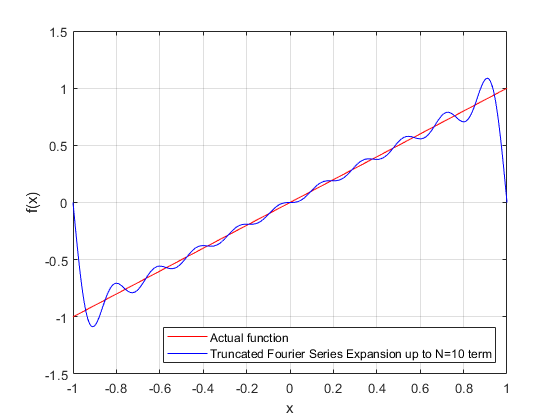

a0 = 1.9299e-17

an = 	1.0e+-17 *

    0.0867    0.4770    0.6288   -0.2602    0.0651    0.2819   -0.2385   -0.0217    0.3686    0.1518


bn =     0.6366   -0.3183    0.2122   -0.1591    0.1273   -0.1061    0.0909   -0.0796    0.0707   -0.0636


%plot(x,y)
[a0, an, bn] = fourierSeries(x, y, 10)

## Fourier Series Function

function [a_0, a_n, b_n] = fourierSeries(xList, fList, N)

L = xList(end) - xList(1);

a_0 = 1/L * trapz(xList, fList);

fSeries = a_0;

for n = 1:N
    a_n(n) = 2/L * trapz(xList, fList.*cos(n*pi*xList/(L/2)));
    b_n(n) = 2/L * trapz(xList, fList.*sin(n*pi*xList/(L/2)));
    fSeries = fSeries + a_n(n).*cos(n*pi*xList/(L/2)) + b_n(n).*sin(n*pi*xList/(L/2));
end



plot(xList, fList, 'r') 
hold on
grid on
xlabel('x')
ylabel('f(x)')
plot(xList, fSeries, 'b')
legend("Actual function","Truncated Fourier Series Expansion up to N="+ N +" term", 'Location','southeast')
hold off
end

## Example Function

function y = f(x)

if x >= -1 && x <= 1 
    y = x; 
else
    y = NaN; 
end

end